filename = '.\data\all_0_floor_cluster_information_k50.csv';

delimiter = ',';
%	열2: double (%f)
% 자세한 내용은 도움말 문서에서 TEXTSCAN을 참조하십시오.
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');
dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string',  'ReturnOnError', false);
fclose(fileID);
clusters = table(dataArray{1:end-1}, 'VariableNames', {'VarName1','VarName2'});
dataArray = table2array(clusters);
[x,y]=size(dataArray);
% x : 클러스터 개수
d_max = 15;
total_table = zeros(x,x);
%%반복문 돌리기 - 인접 클러스터 찾기
for i=1:1:x
    min = 99999;
    min_idx = 0;
    has_near_cluster = 0;
    total_table(i,i) = i;
    for j = 1:1:x
        if i == j
            continue;
        end
        c_x = dataArray(i,1);
        c_y = dataArray(i,2);
        cc_x = dataArray(j,1);
        cc_y = dataArray(j,2);
        d = sqrt((c_x - cc_x)^2 + (c_y - cc_y)^2);
        if d <= d_max
           %[i j d]
           total_table(i,j) = j;
           total_table(j,i) = i;
           has_near_cluster = 1; 
        elseif min > d
            min = d;
            min_idx = j;
        end
    end
    if has_near_cluster == 0
        total_table(i,min_idx) = min_idx;
        total_table(min_idx,i) = i;
    end
end

## **Total_table 값으로 만들어진 클러스터 간의 연결성 표시**

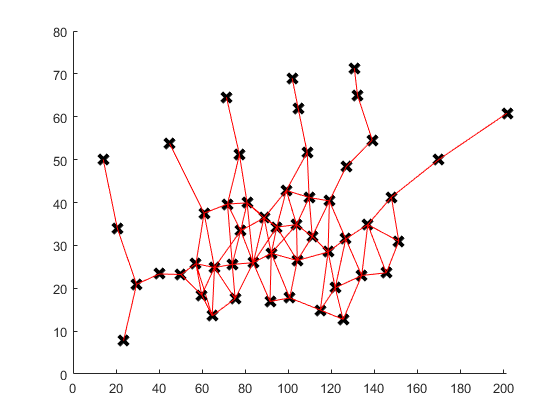

figure;
hold on
for i=1:1:x
    c_x = dataArray(i,1);
    c_y = dataArray(i,2);    
    plot(c_x,c_y,'kx','MarkerSize',10,'LineWidth',3);
    for j=1:1:x
        
        if total_table(i,j) > 0
            cc_x = dataArray(j,1);
            cc_y = dataArray(j,2);
            data_x = [ c_x cc_x];
            data_y = [ c_y cc_y];
            plot(data_x,data_y,'r-');
        end
        
    end
end
hold off

테이블 값으로 경로생성하기

- 생성할 데이터 갯수 지정

- 경로 길이 지정

- 파일로드

- 데이터 개수만큼 반복

- 경로길이만큼 반복

- 이동할 수 있는 노드로 동일한 확률로 변경

- 해당 노드에 속한 데이터 랜덤 추출 및 기록

- 마지막 노드의 위칫값 기록

- output.csv파일에 데이터 누적

num = 5000; % 데이터 생성 개수 
path = 5;    % 이동경로 길이
k=50;        % 클러스터 개수
data_type = 'test';%'test' or 'train'
output_file_name = strcat('.\data\output_k',num2str(k),'_p',num2str(path),'_',data_type,'.csv');
filename = strcat('.\data\all_0_floor_cluster_idx_k',num2str(k),'_',data_type,'.csv');
delimiter = ',';

formatSpec = '%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%[^\n\r]';

fileID = fopen(filename,'r');

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string', 'EmptyValue', NaN,  'ReturnOnError', false);

fclose(fileID);

%% 출력 변수 만들기
all0floorclusteridxk50 = table(dataArray{1:end-1});

dataArray = table2array(all0floorclusteridxk50);
%[row, col] = size(dataArray);
dataX = dataArray(:,1:end-3);   
dataY = dataArray(:,end-2:end-1);
cluster_idx = dataArray(:,end);

s = RandStream('mlfg6331_64');

for i=1:1:num
    %시작지점 뽑기
    idx = round(rand() * (x-1) + 1);
    node_datas = dataX(cluster_idx==idx, : );
    pathdata_x = datasample(s,node_datas,1);
    
    for j = 2:1:path
        next_path = total_table(idx,total_table(idx,:)~=0);
        idx = datasample(s,next_path,1);
        
        if j == path
            node_datas = dataArray(cluster_idx==idx, 1:end-1 );
            next_data = datasample(s,node_datas,1);
        else
            node_datas = dataX(cluster_idx==idx, : );
            next_data = datasample(s,node_datas,1);
        end
        pathdata_x = [ pathdata_x next_data];
    end
    if size(pathdata_x,2) ~= path*992 + 2 
        i=i-1;
        continue;
    end
    dlmwrite(output_file_name, pathdata_x,'delimiter',',','-append');
end





## 임시 변수 지우기

clearvars filename delimiter formatSpec fileID dataArray ans;